clear;
clc;
bode_plot_options = bodeoptions();
bode_plot_options.Grid = 'on';

# Plant

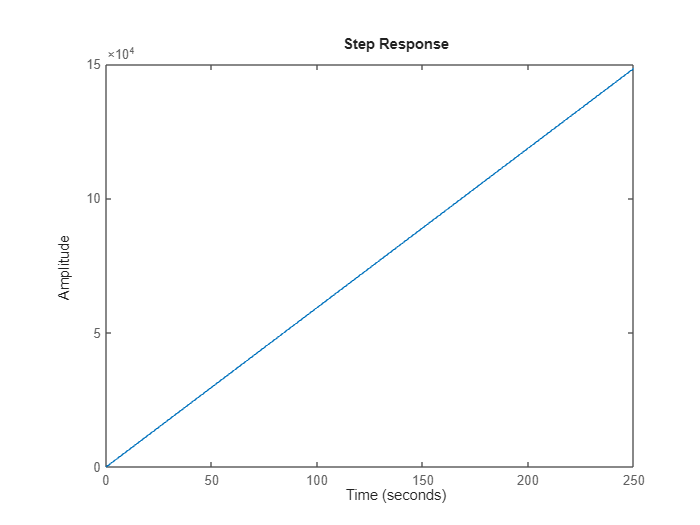

A = [-33.95 0; 360 0];
B = [55.99; 0];
C = [0 1];
plant_ss = ss(A,B,C,0);
step(plant_ss);

% Controlability verification
rank(ctrb(A,B))

ans = 2

## Discretization

Ts = 0.005;
plant_ss_discrete = c2d(plant_ss,Ts,'zoh');
pole(plant_ss_discrete)

ans =     1.0000
    0.8439


# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0

## 1. Pole Placement + IMP 

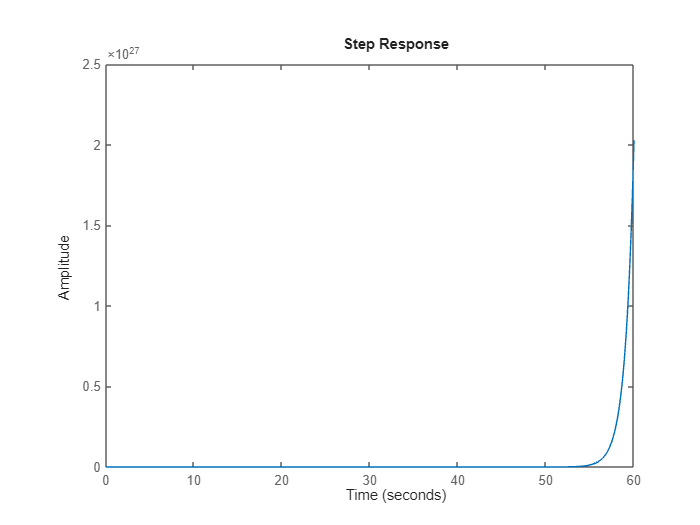

% Pole selection in continuous
s1 = 2;
s2 = 1;
% Pole convertion e^(-Ts*s)
p = [exp(-Ts*s1), exp(-Ts*s2)];
% K calculation
K = place(plant_ss_discrete.A,plant_ss_discrete.B,p);


Acl = plant_ss_discrete.A-plant_ss_discrete.B*K;
syscl = ss(Acl,plant_ss_discrete.B,plant_ss_discrete.C,plant_ss_discrete.D);
step(syscl)

## 2. Pole Placement + IMP + Ludenberg estimator 

## *3. LQR + IMP*

## *4. LQG + IMP*